# Power-Split HEV with Speed Tracking - Additional Tests

Copyright 2021-2022 The MathWorks, Inc.

## Open the Model

mdl = "PowerSplitHEV_SpeedTracking";
if not(bdIsLoaded(mdl)), load_system(mdl); end

## Load Inputs to Workspace

input_pattern = "all_zero";

Load vehicle speed reference

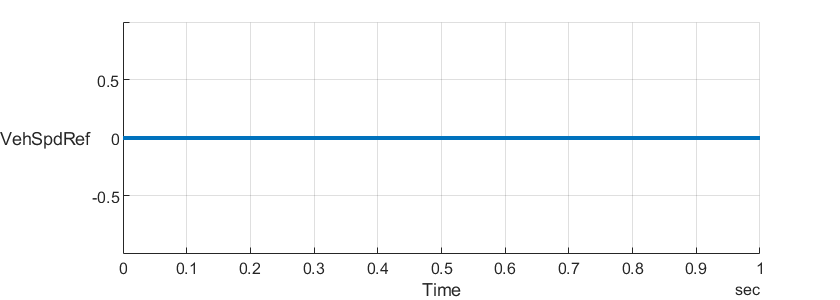

fig = figure;
[inputSignals_DrivingPattern, inputBus_DrivingPattern, initial_DrvPtn, opt] = ...
  DrivingPatternBasic_inputs( "PlotParent",fig, "PlotSpeedOnly",true, ...
    "InputPattern", input_pattern );
fig.Position(4) = 200;  % height

drivingPattern.useFromWorkspace_tf = opt.useFromWorkspace;

Load road grade

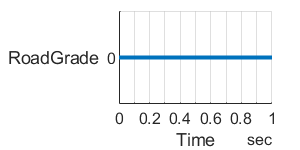

fig = figure;
[inputSignals_RoadGrade, inputBus_RoadGrade, opt2] = ...
  DriverAndEnvironment_road_grade_pattern( "PlotParent",fig, "InputPattern", "flat" );
fig.Position(3:4) = [200 100];  % width height

Set simulation time

t_end = max(opt.t_end, opt2.t_end);
clear t_end_2

## Run Simulation

Load default parameters

% Plant
PowerSplitHEV_params

% Controller/Driver - load this after plant
HEVPowerSplitControl_params

Override initial conditions and block parameter values

% initial.driverHVBattSOC_pct = initial_DrvPtn.HVBattery_SOC_pct;
initial.driverHVBattSOC_pct = 75;

initial.driverBrakeForce_N = 8000;
initial.driverBrakeOn_tf = true;

initial.vehicleSpeed_kph = 0;
initial.motorGenerator2_speed_rpm = 0;
initial.motorGenerator1_speed_rpm = 0;
initial.engine_speed_rpm = 0;
initial.engine_torque_Nm = 0;

Set simulation input

simIn = Simulink.SimulationInput(mdl);
simIn = setModelParameter(simIn, 'StopTime',num2str(t_end));

Run simulation

simOut = sim(simIn);

Error evaluating parameter 'dt' in 'PowerSplitHEV_SpeedTracking/Controller & Environment/Driving Pattern/Drive Cycle Source'

Caused by:
    Error using Simulink.Simulation.internal.DesktopSimHelper>@(simIn)builtin('sim',simIn)
    Unrecognized function or variable 'dt'.
        Error using Simulink.Simulation.internal.DesktopSimHe

Simulated time (sec)

t_end

Elapsed wall-clock time (sec)

t_elapsed = simOut.SimulationMetadata.TimingInfo.TotalElapsedWallTime

Speed up

t_end / t_elapsed

## Visualize Simulation Result

Vehicle

fig = figure;
PowerSplitHEV_SpeedTracking_plot_result_vehicle( "Dataset",simOut.logsout, "PlotParent",fig );

High Voltage Battery

fig = figure;
fig.Position(3:4) = [600 500];  % width height
PowerSplitHEV_SpeedTracking_plot_result_hvbattery( "Dataset",simOut.logsout, "PlotParent",fig );

Power-Split Drive Unit

fig = figure;
PowerSplitHEV_SpeedTracking_plot_result_powersplit( "Dataset",simOut.logsout, "PlotParent",fig );